# TCLAB Linearize Energy Balance

**Objective:** Linearize and simulate and energy balance model with radiative and convective heat transfer

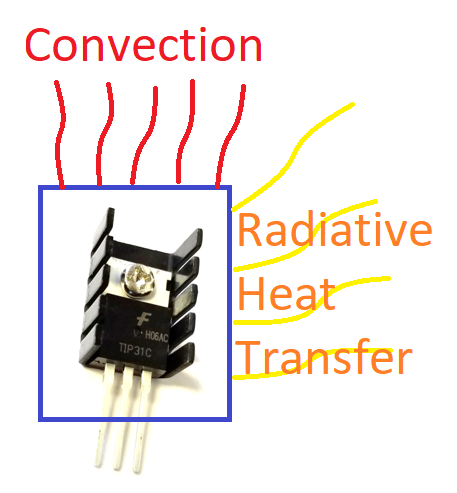

An energy balance equation includes convective and radiative heat transfer and is nonlinear because of the $T^4$ term.


$$\frac{dT}{dt} = f(T,Q) = \frac{U\,A\, \left(T_a-T\right) +  \epsilon\,\sigma\,A\,\left(T_\infty^4-T^4\right) + \alpha \, Q}{m \, c_p}$$


Linearize the nonlinear differential equation by computing the partial derivatives $\gamma$ and $\beta$ with respect to the heater value ($Q$) and temperature ($T$). The $\gamma$ and $\beta$ are constants when evaluated at steady state conditions. The right hand side of the differential equation is a function $f(T,Q)$ of only $Q$ and $T$ while the other values are constants.


$$\frac{dT}{dt} = \frac{\partial f}{\partial T}\bigg|_{\bar T,\bar Q} \left(T-\bar T\right) + \frac{\partial f}{\partial Q}\bigg|_{\bar T,\bar Q} \left(Q-\bar Q\right)$$


### **Condensed Linear Form**


$$\frac{dT'}{dt} = \gamma T' + \beta Q'$$


with partial derivatives evaluated at steady state conditions ($\bar Q=0$, $\bar T=23^\circ \text{C}$):


$$\gamma = \frac{\partial f}{\partial T}\bigg|_{\bar T,\bar Q}$$



$$\beta = \frac{\partial f}{\partial Q}\bigg|_{\bar T,\bar Q}$$


and deviation variables as the difference from the steady state conditions:


$$T'=T-\bar T$$



$$Q'=Q-\bar Q$$


### Problem Statement

Run the TCLab at 75% power for 5 minutes. Compare the experimental results to the predicted results using **1) a nonlinear model** developed last TCLab activity in the *Radiative Heat Transfer* activity and **2) a Linear model** using the linearized equation above. In total, there should be three entities on the graph: The data from the TCLab, the nonlinear model, and the linearized model. Use values $\alpha=0.01
$, $T_a=23^\circ \text{C}$, $m=0.004 \text{kg}$, $\epsilon=0.9$, $A=0.0012\text{m}^2$, $c_p=500\frac{\text{J}}{\text{kg K}}
$, $U=5\frac{\text{W}}{\text{m}^2\text{ K}}$, $\sigma=5.67*10^{-8} \frac{\text{W}}{\text{m}^2\text{ K}^4}$, and $T_\infty=23^\circ\text{C}$.

Initialize time array and set csv filename

clc; clear all; close all;
tmp = matlab.desktop.editor.getActive;
directory = fileparts(tmp.Filename);


n = 700;  % number of seconds to test
time = linspace(0, n, n+1);

% Collect data
filename = "L5_TCLab_data.csv";
absolute_path = fullfile(directory, filename);

Read TCLab data from file named before if it exists, otherwise, generate data

try % try to read from file first
    A = readmatrix(absolute_path)
    tm = A(:,1);
    T1 = A(:,2);
    disp('TCLab Data read from file')
    
catch % if file can not be found, simulate
    try 
        % initialize lab
        lab = tclab;
        
        % loop through
        T1 = zeros(n+1, 1);
        tm = zeros(n+1, 1);
        lab.Q1(75);
        tic;
        for i=1:n+1
            tm(i) = toc;
            T1(i) = lab.T1;
            plot(tm(1:i), T1(1:i), 'r.')
            xlabel('Time (sec)')
            ylabel('Temperature (C)')
            pause(1);
        end
        lab.off;
        clear lab;
        
        % save
        A = [tm T1]
        writematrix(A, absolute_path, 'Delimiter', ',')
        
    catch % if an error, turn off heater and close
        lab.off;
        clear lab;
    end
    
end

A =     0.0003   21.6520
    1.6819   21.6520
    3.0486   21.7498
    4.3804   21.6031
    5.6804   21.7986
    7.0284   21.5543
    8.3594   21.7498
    9.6412   21.8964
   10.9715   22.2874
   12.2973   22.2874


TCLab Data read from file


CREATE A FUNCTION NAMED **TCLabSim **WHICH RETURNS BOTH A LINEARIZED AND NONLINEAR DIFFERENTIAL TEMPERATURE FOR THE TCLab

**Hint:** The function should return a column vector for use in `ode45` like the following example:

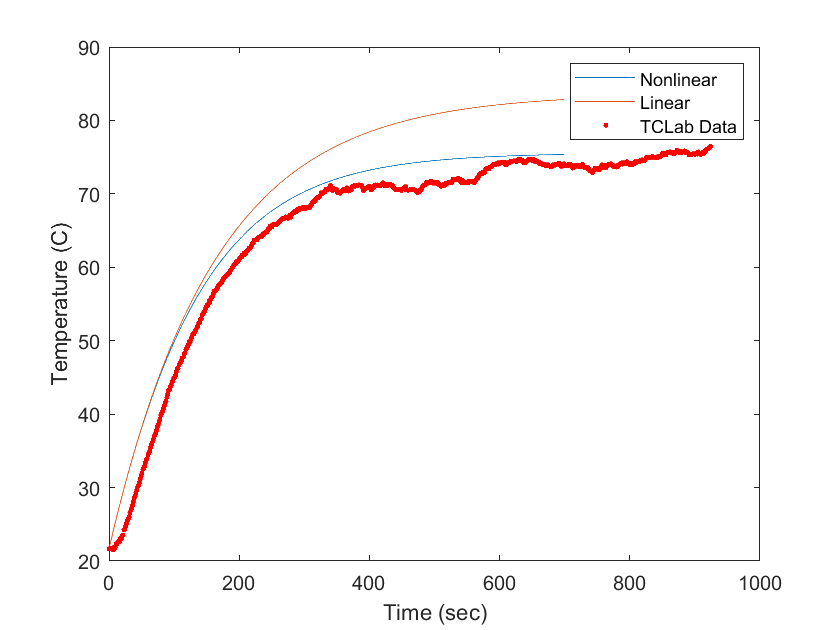

[t, T] = ode45(@(t,T) TCLabSim(t, T, 75), time, [T1(1); T1(1)]);

% separate results
T_l = T(:,1);
T_nl = T(:,2);

% plot
plot(t, [T_nl T_l])
hold on;
plot(tm, T1, 'r.')
legend('Nonlinear', 'Linear', 'TCLab Data')
xlabel('Time (sec)')
ylabel('Temperature (C)')
hold off

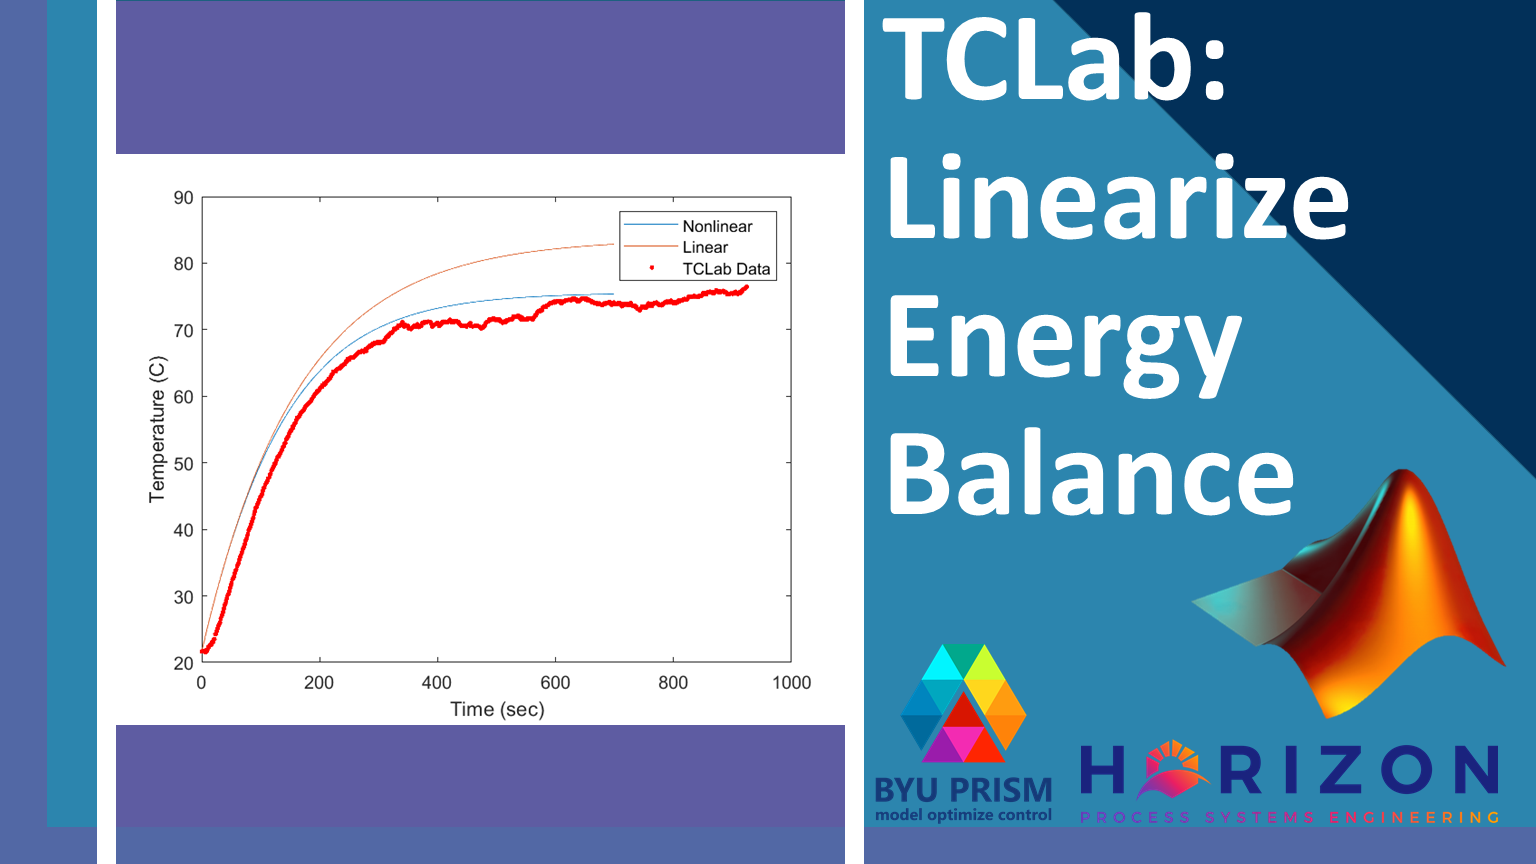

### [View Solution Video](https://youtu.be/9HcDSzUUR_M)

viewSolution(false)

function viewSolution(view)
if view
	disp("function dT = TCLabSim(~, T, Q)" + newline + ...
	     "    % unpack Temperatures" + newline + ...
	     "    T_linear = T(1);" + newline + ...
	     "    T_nonlinear = T(2); " + newline + ...
	     "    " + newline + ...
	     "    % constants" + newline + ...
	     "    U = 5.0;" + newline + ...
	     "    A = 0.0012;" + newline + ...
	     "    alpha = 0.01;" + newline + ...
	     "    epsilon = 0.9;" + newline + ...
	     "    sigma = 5.67e-8;" + newline + ...
	     "    Cp = 500;" + newline + ...
	     "    m = 0.004;" + newline + ...
	     "    " + newline + ...
	     "    Tss = 23;  % Steady State Temperature" + newline + ...
	     "    Tss_k = Tss + 273.15;  % Steady State Temperature in K" + newline + ...
	     "    Qss = 0;  %  Steady State Heater Setting" + newline + ...
	     "    " + newline + ...
	     "    % calculate gamma and beta for linearized model" + newline + ...
	     "    gamma = -U*A/(m*Cp) - 4*epsilon*sigma*A*Tss_k.^3/(m*Cp);" + newline + ...
	     "    beta = alpha/(m*Cp);" + newline + ...
	     "    " + newline + ...
	     "    % linear model" + newline + ...
	     "    dTdt_linear = gamma * (T_linear-Tss) + beta * (Q-Qss);" + newline + ...
	     "    % nonlinear" + newline + ...
	     "    Tk = T_nonlinear + 273.15;" + newline + ...
	     "    dTdt_nonlinear = (U*A*(Tss-T_nonlinear) + sigma*epsilon*A*(Tss_k.^4-Tk.^4) + alpha*Q)/(m*Cp);" + newline + ...
	     "    " + newline + ...
	     "    % Pack results" + newline + ...
	     "    dT = [dTdt_linear; dTdt_nonlinear];" + newline + ...
	 "end")
end
end
